% Study all products (BEC) available and see how this perfom within the
% Baltic region.
% The product to look at are:
% * [1] Baltic+ Salinity NOMINAL product(v1.0)
% * [2] Baltic+ Salitniy Nodal Sampling product (v1.0)
% * [3] Baltic BEC Global (v001)
%
% Author: rcatany
% Date  : 20191119
%
% History
% Version | Date| Note
% v1r0 [24/10/2019] : Creation of this script

%==========================================================================
clear 
clc
close all

% Example (settings)
ibasin = 9;     % Basin number Arctic [ibasin 7]; Baltic [ibasin 9]

iyear = 2013;
imonth = 2;
iday = 1;

itime = datenum(iyear,imonth,iday);

date_str = datestr(itime,'yyyymmdd');

warning('off','all')

## 1/ SSS in each product [MERCATOR projection]

### *[1.1] Baltic BEC NOM product (v1.0)

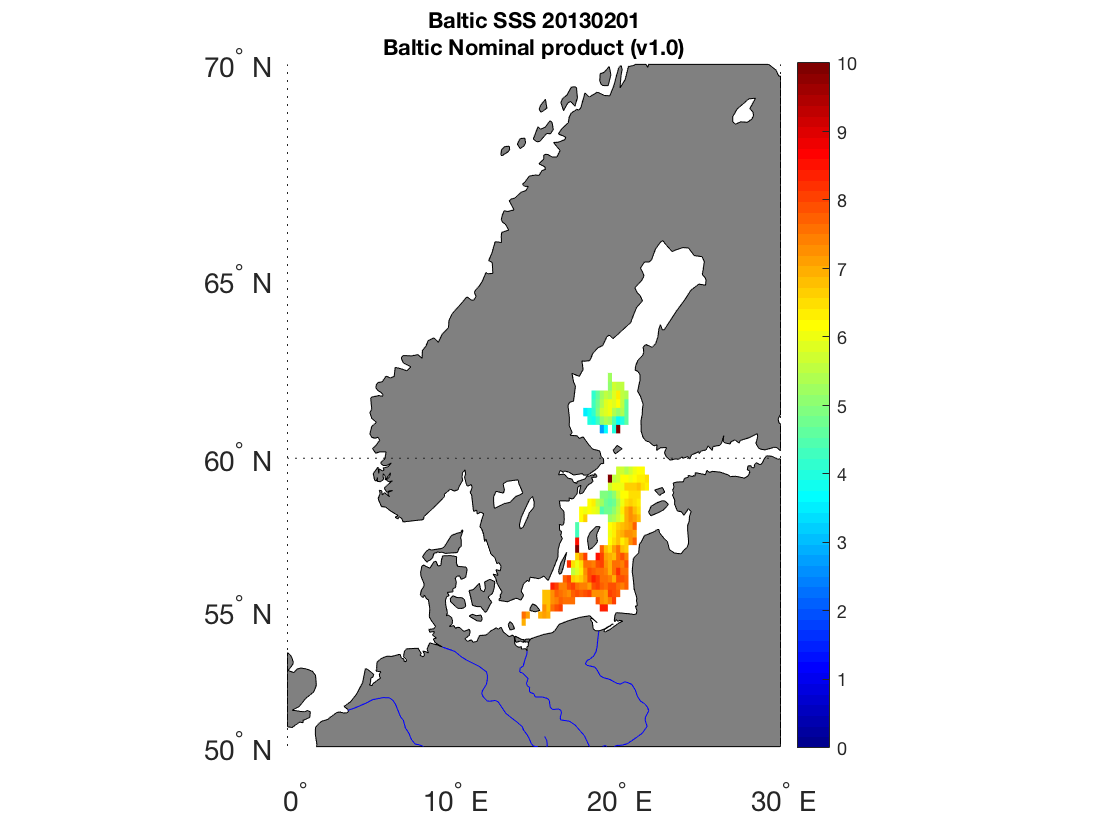

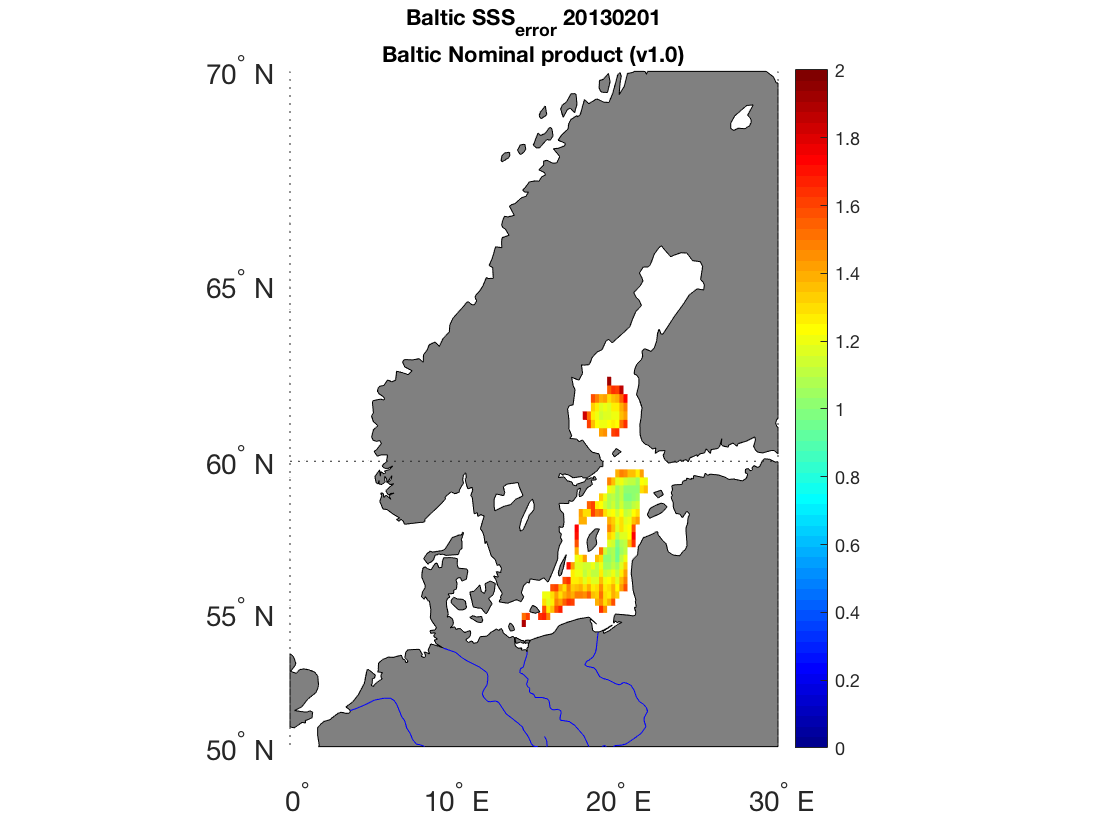

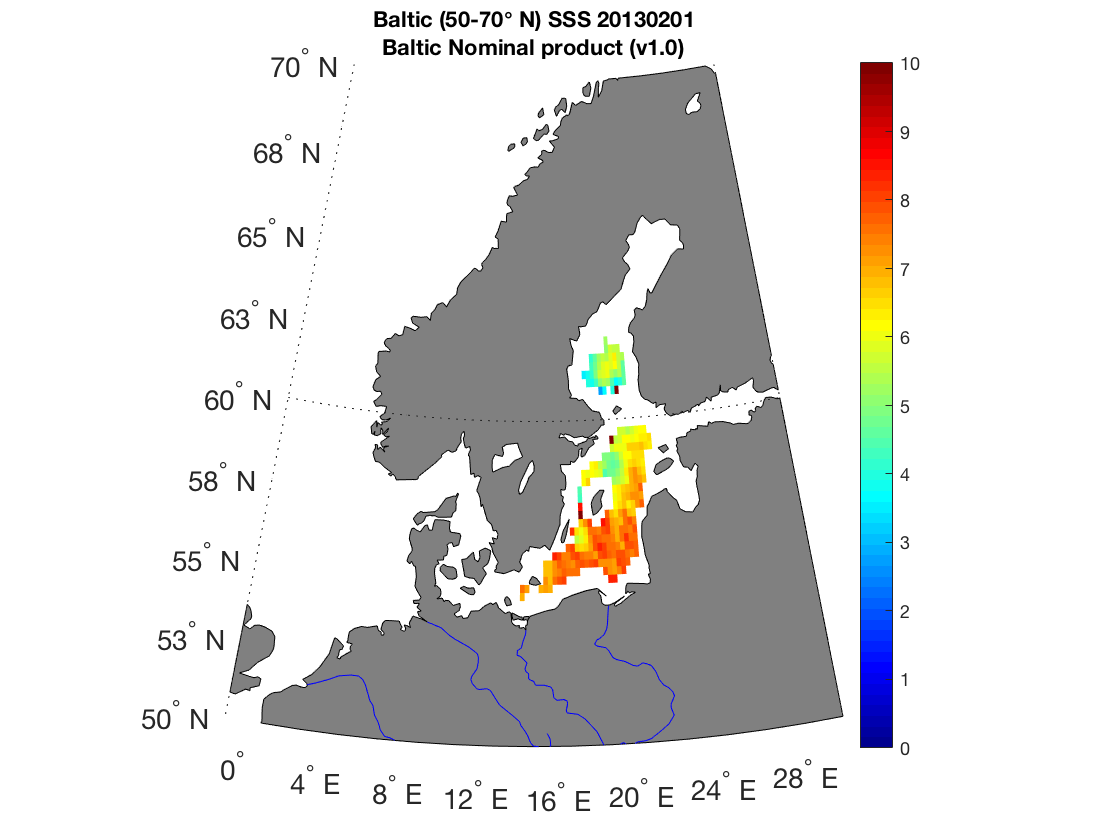

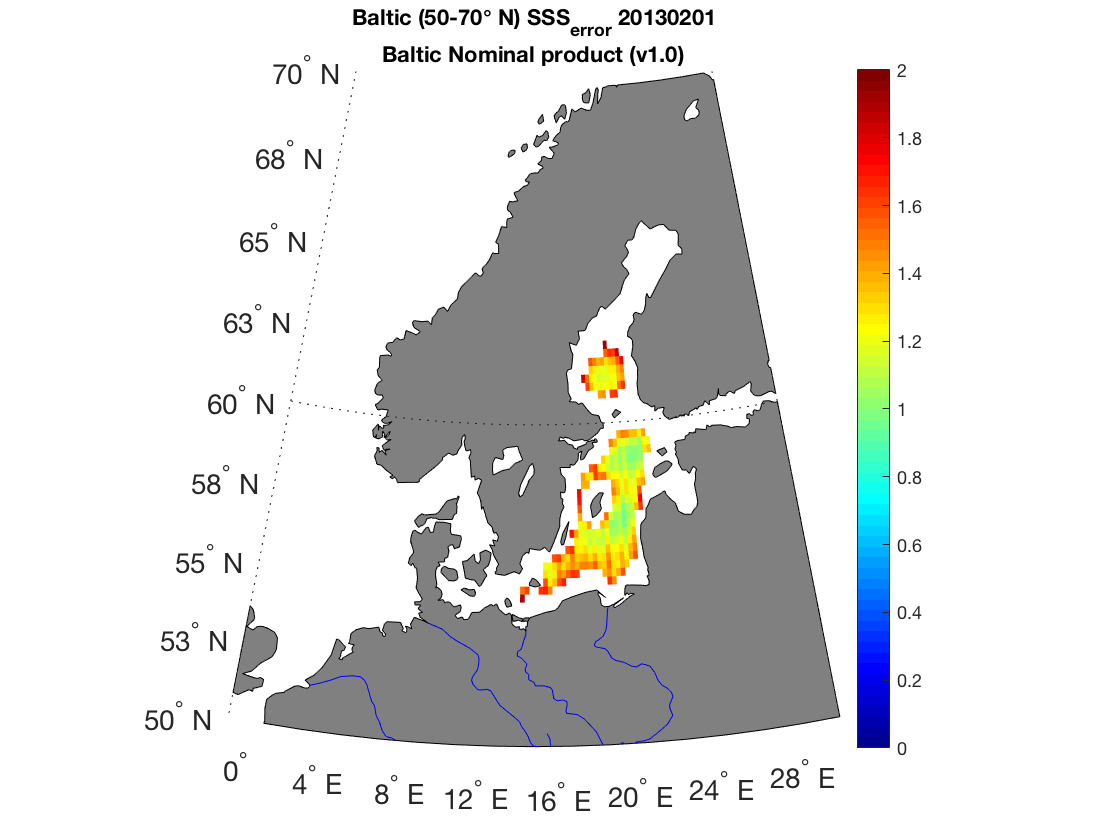

data_type = 4;  % [4] Baltic+ NOM (v1.0), [5] Baltic NS (v1.0), [6] Global BEC
plot_type = 1;  % [1] Mercator, [2] Polar, [3] Lambert (conical), [4] All-plots
region = 'Baltic';
Baltic_plot_fun(ibasin,itime,data_type,plot_type,region)

### *[1.2] Baltic+ NS product (v1.0)

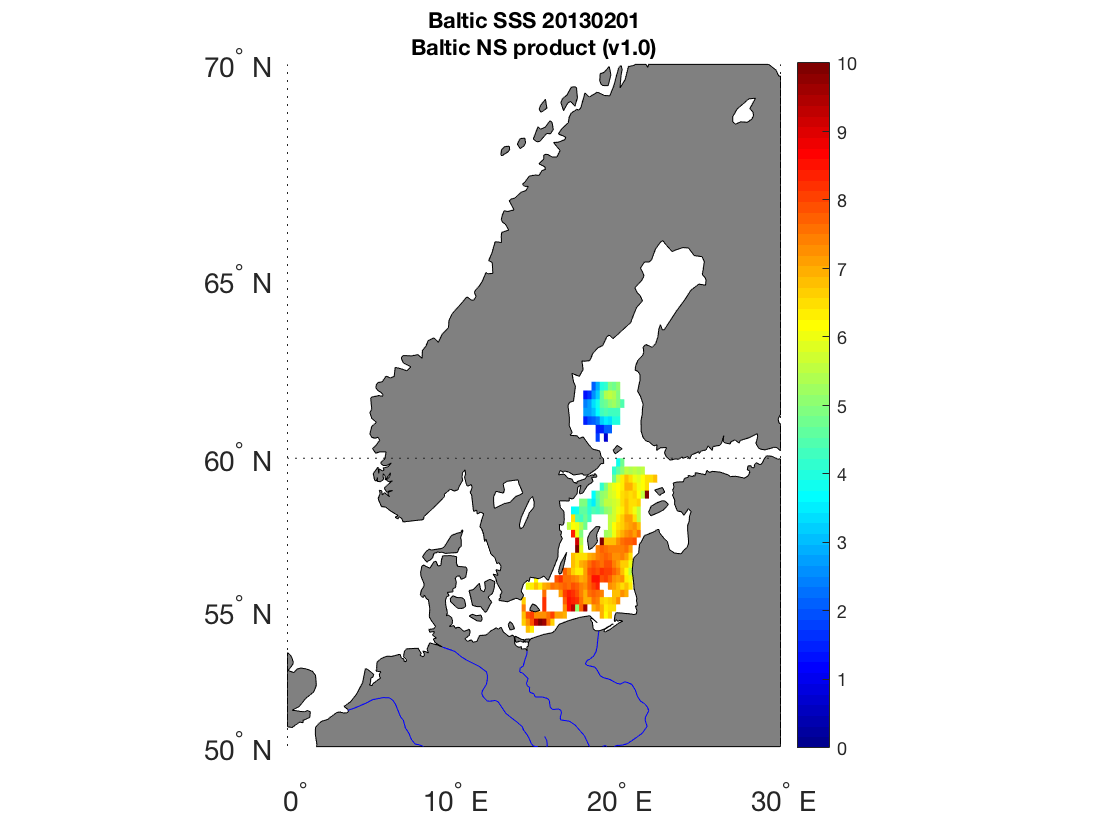

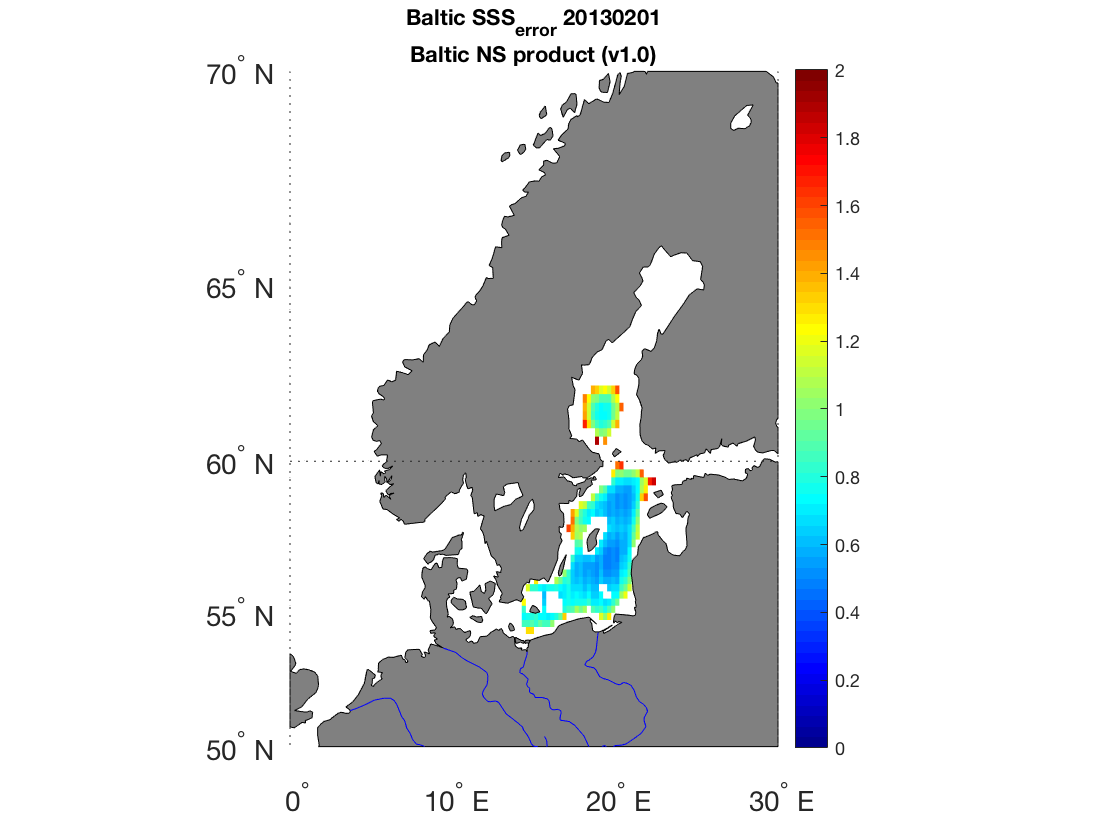

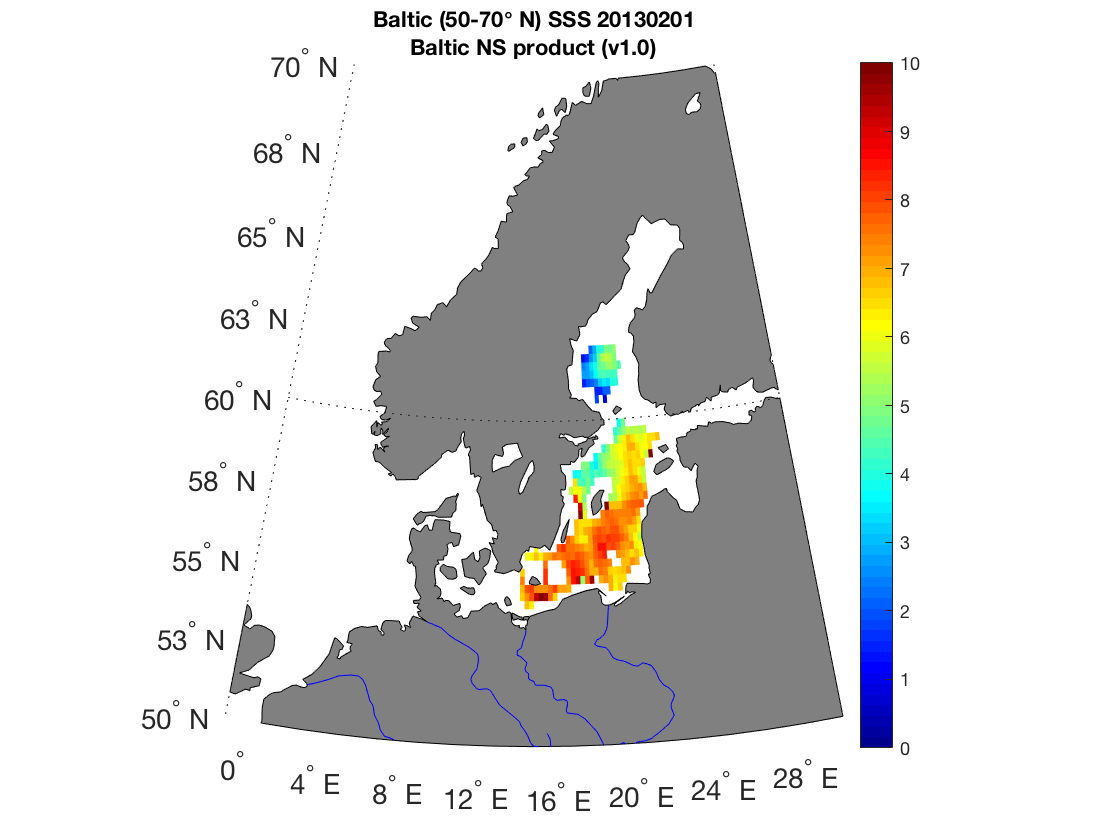

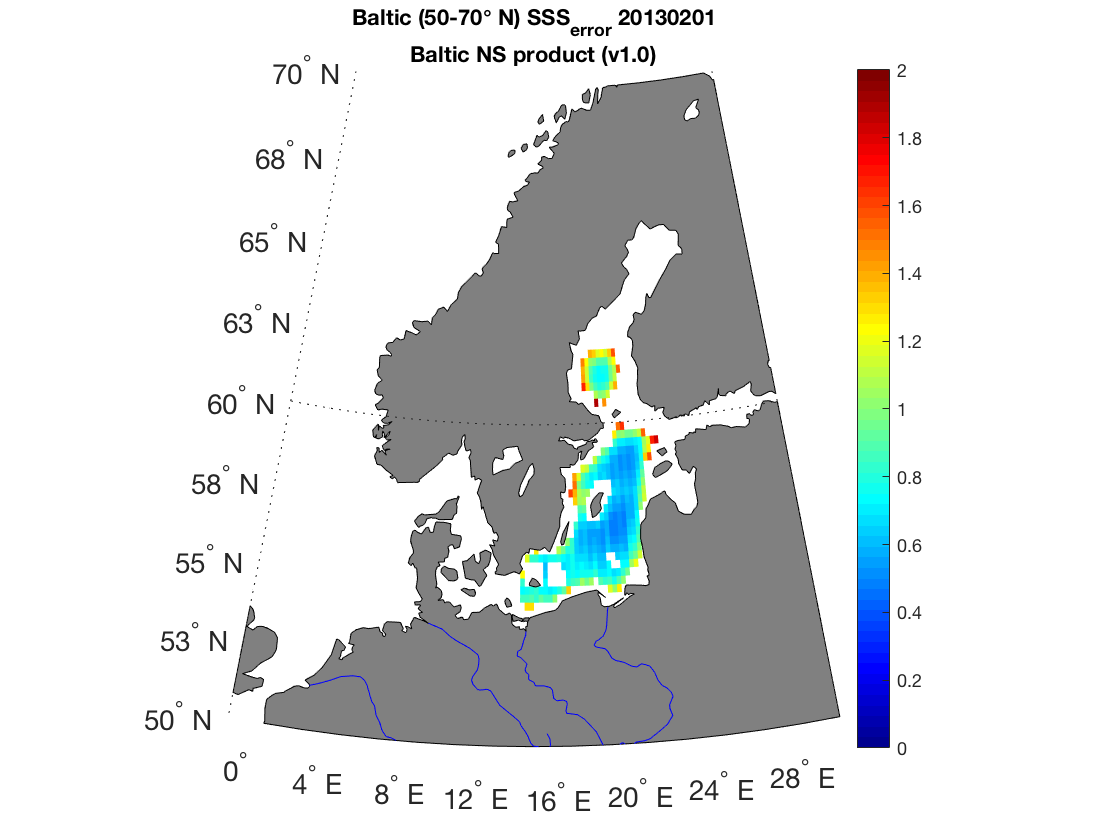

data_type = 5;  % [4] Baltic+ NOM (v1.0), [5] Baltic NS (v1.0), [6] Global BEC
plot_type = 1;  % [1] Mercator, [2] Polar, [3] Lambert (conical), [4] All-plots
region = 'Baltic';
Baltic_plot_fun(ibasin,itime,data_type,plot_type,region)

### *[1.3] Global product (v001) in the Baltic region

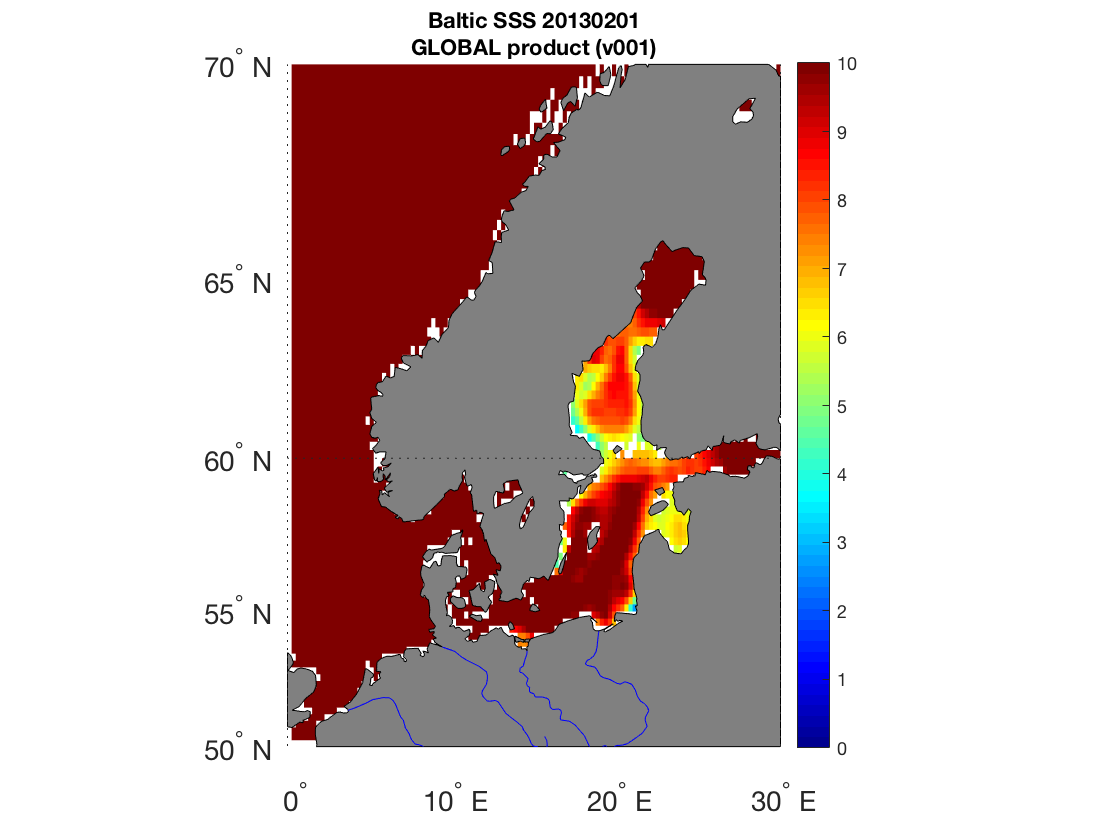

if iyear <= 2016
data_type = 6;  % [4] Baltic+ NOM (v1.0), [5] Baltic NS (v1.0), [6] Global BEC
plot_type = 1;  % [1] Mercator, [2] Polar, [3] Lambert (conical), [4] All-plots
region = 'Baltic';
Baltic_plot_fun(ibasin,itime,data_type,plot_type,region)
end

## 2/ SSS in each product in North Atlantic Subpolar [LAMBERT-conical projection]

### *[2.1] Baltic BEC NOM product (v1.0)

data_type = 4;  % [4] Baltic+ NOM (v1.0), [5] Baltic NS (v1.0), [6] Global BEC
plot_type = 3;  % [1] Mercator, [2] Polar, [3] Lambert (conical), [4] All-plots
region = 'Baltic';
Baltic_plot_fun(ibasin,itime,data_type,plot_type,region)

### *[2.2] Baltic+ product (v1.0)

data_type = 5;  % [4] Baltic+ NOM (v1.0), [5] Baltic NS (v1.0), [6] Global BEC
plot_type = 3;  % [1] Mercator, [2] Polar, [3] Lambert (conical), [4] All-plots
region = 'Baltic';
Baltic_plot_fun(ibasin,itime,data_type,plot_type,region)

### *[2.3] Global product (v001) in the Arctic region

if iyear <= 2016
data_type = 6;  % [4] Baltic+ NOM (v1.0), [5] Baltic NS (v1.0), [6] Global BEC
plot_type = 13;  % [1] Mercator, [2] Polar, [3] Lambert (conical), [4] All-plots
region = 'Baltic';
Baltic_plot_fun(ibasin,itime,data_type,plot_type,region)
end

## 3/ Plot ANOMALIES computed from each product - Not possible [Baltic+ 2011-2013]

% *[1] Baltic BEC product (v2.0)
% data_type = 2;  % [1] Arctic+ (v3.0), [2] Arctic BEC (v2.0), [3] Global BEC
% Arctic_CLIMAT_plot_fun (ibasin,iyear,imonth,data_type)
% % *[2] Arctic+ product (v3.0)
% 
% data_type = 1;  % [1] Arctic+ (v3.0), [2] Arctic BEC (v2.0), [3] Global BEC
% Arctic_CLIMAT_plot_fun (ibasin,iyear,imonth,data_type)
% % *[2] Global product (v001) in the Arctic region
% 
% if iyear <= 2016
% data_type = 3;  % [1] Arctic+ (v3.0), [2] Arctic BEC (v2.0), [3] Global BEC
% Arctic_CLIMAT_plot_fun (ibasin,iyear,imonth,data_type); 
% end